% Motor parameters
J = 0.01;
Km = 0.01;
Bm = 0.1;
L = 0.5;
R = 1;

% Motor model
A = [0 1 0; 0 -Bm/J Km/J; 0 -Km/L -R/L];
B = [0 0; 1/J 0; 0 1/L];
Bt = B(:, 1);
Bv = B(:, 2);
C = [0 1 0];
D = [0 0];

motor = ss(A, B, C, D, 'InputName', {'t', 'V'}, 'OutputName', 'a', 'StateName', {'a', 'w', 'i'});
h = stepplot(motor(1))


h =

	resppack.timeplot



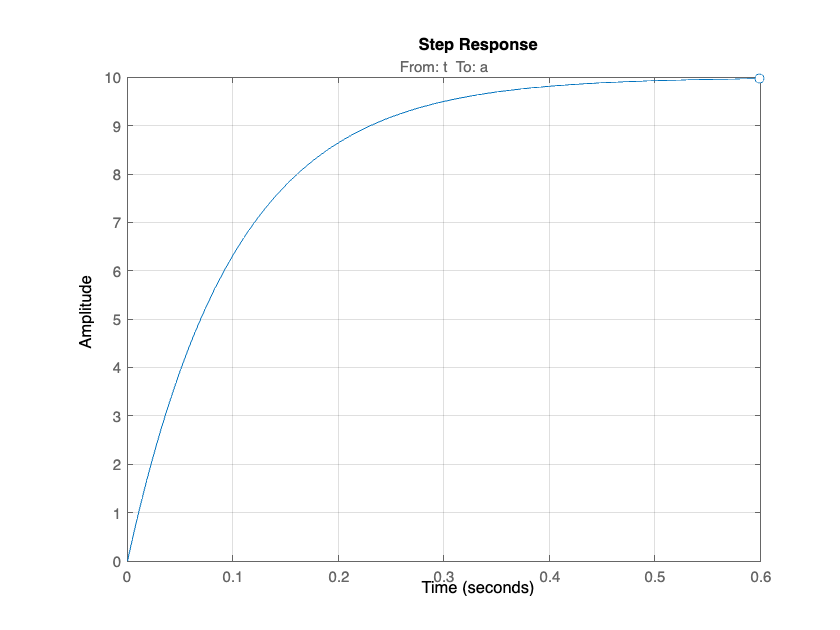

h.showCharacteristic('SettlingTime')
h.showCharacteristic('RiseTime')
grid on;